# **drawCircle**

# **fillCircle**

Draw or fill the Circular arc

## Description

 Parametric equations of the circular arc are

$x=x_c +r\;\mathrm{cos}\theta$, $y=y_c +r\;\mathrm{sin}\theta$,    $\theta_0 \le \theta {\le \theta }_0 +\Delta \theta$.

where *r *is radius.

## Syntax

drawCircle( xc, yc, r)

drawCircle( xc, yc, r, sang, theta)

drawCircle( xc, yc, r, sang, theta, '-pie')

drawCircle( xc, yc, r, sang, theta, '-seg')

drawCircle( __, '-np',np)

drawCircle( __,  LineSpec)

p = drawCircle(__)

fillCircle(c, __)

## Description

drawCircle( xc, yc, r) draw the circle with default number of points 360 and current line specification. 

drawCircle( xc, yc, r, sang, theta) draw the circular arc with  number of points set to fix(theta) and current line specification. 

drawCircle( xc, yc, r, sang, theta,'-pie') draw a pie i.e. connect end points with the center. 

drawCircle( xc, yc, r, sang, theta,'-seg') draw a segment i.e. connect end points. 

drawCircle( __, LineSpec)  sets the line style, line width, and color.

drawCircle( __,'-np',np) set the number of points on the output curve.

p = drawCircle(__) returns structure with fields contains coordinates of end points.

## Method

For calculation of the coordinates of the curve **drawCircle **call function **evalCircle( xc,yc,r,th)  **which returns coordinates *x *and *y *of the curve at given angles th . For usage of **evalCircle **see Example 1.

The curve is plotted by MATLAB function [plot](https://www.mathworks.com/help/matlab/ref/plot.html).

## Arguments

### Input Arguments

**c **- fill color

**xc - **x-coordinate of the center (real scalar)

**yc **- y-coordinate of the center (real scalar)

**r **- circle radius (real scalar)

### **Optional Input Argumnts**

**sang** - start angle in degrees

**theta **- central angle in degrees: > 0 if CCW, <0 if CW

**'-pie'|'-sec'** - draw pie (section)

**'-seg'** -  segment

### Optional Name-Value Pair Input Arguments

**'-np',** **np **- number of points along the curve ( scalar integer value > 2)

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure with fields

- p.xk, p.yk - key points: 1=start,2=end,3=center

- p.th - tangent angle: 1=start,2=end 

- p.color - line color

## Examples

### Example 1

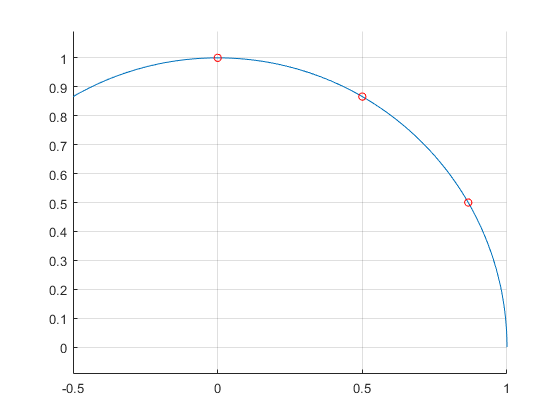

%Data 
r = 1;
sang = 0;
theta = 120;
% plot
figure
hold on
axis equal
[x,y] = evalCircle(0,0,r,linspace(sang,sang + theta));
plot(x,y)
[x,y] = evalCircle(0,0,r,[30,60,90]); % points on circle
scatter(x,y,30,'r')
grid on

### Example 2

%Data 
xc = 0;
yc = 0;
r = 1;
sang = 30;
theta = 150;
figure
hold on
axis equal
c1 = drawCircle(xc,yc,r)

c1 = struct with fields:
       xk: [-1 1 0 0 0]
       yk: [0 0 -1 1 0]
       th: [90 90]
    color: 'k'


c2 = drawCircle(xc,yc,r/2,sang,theta,'-pie','LineWidth',2,'Color','r','-np',100)

c2 = struct with fields:
       xk: [0.4330 -0.5000 0]
       yk: [0.2500 0 0]
       th: [120.0000 -90]
    color: [1 0 0]


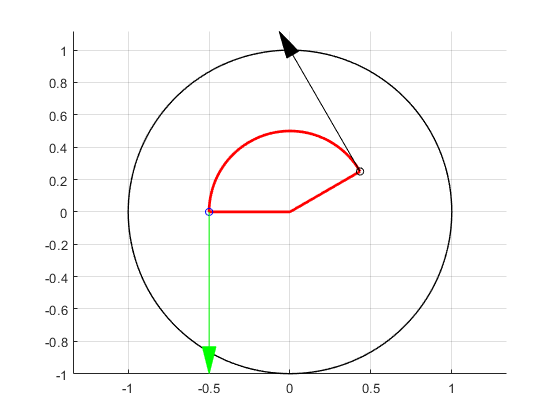

scatter(c2.xk(1),c2.yk(1),30,'k')
scatter(c2.xk(2),c2.yk(2),30,'b')
drawArrow(3,0.5/3,0.25/3,c2.xk(1),c2.yk(1),'-rtheta',1,c2.th(1),'k')
drawArrow(3,0.5/3,0.25/3,c2.xk(2),c2.yk(2),'-rtheta',1,c2.th(2),'g')
grid on

### Example 3

%Data 
xc = 0;
yc = 0;
r = 1;
sang = 30;
theta = 150;
figure
hold on
axis equal
c1 = drawCircle(xc,yc,r);
c2 = drawCircle(xc,yc,r/2,sang,theta,'-pie','LineWidth',2,'Color','r','-np',100);
c3 = fillCircle('g',xc,yc,r/3,-sang/3,-theta,'-seg','LineWidth',1,'-np',100);
grid on

### Example 4

% intercept errors
figure
hold on
axis equal
p = drawCircle(0,0,10,2,i,'-np',16)
grid on

### Example 6

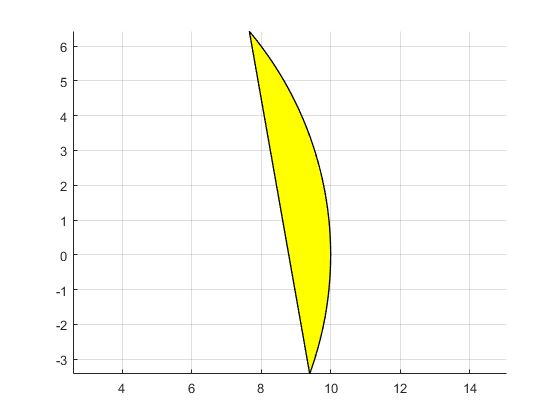

figure
hold on
axis equal
p = fillCircle('y',0,0,10,-20,60,'-seg');
p = drawCircle(0,0,10,-20,60,'-seg');
grid on

### Example 7

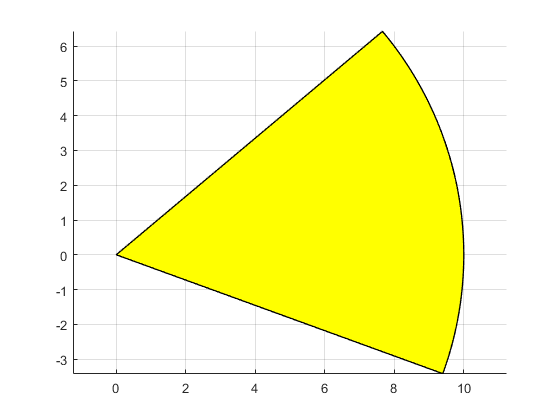

figure
hold on
axis equal
p = fillCircle('y',0,0,10,-20,60,'-sec');
p = drawCircle(0,0,10,-20,60,'-sec');
grid on

## **See Also**

## References